# Question 8

#### In collaboration with Nicholas Law

Did not get to the Kalman filter analysis.

## Cruise Control Pole Placement Design

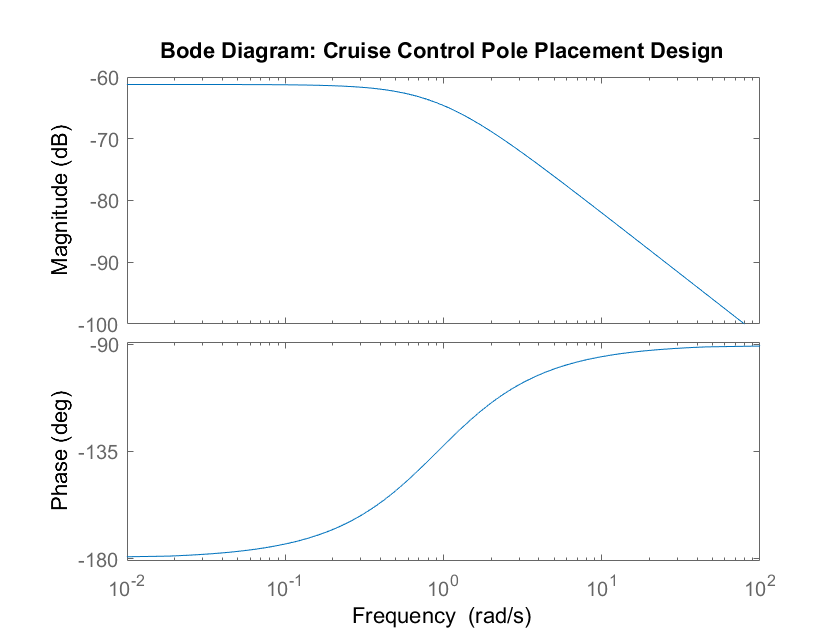


Acc = [-100/2000];
Bcc = [1/2000];
Ccc = [1];
Dcc = [0];
Kcc = -0.25;
hcc = 1.74;
funcc = @(x) expm(Acc*hcc);
phicc = expm(Acc*hcc);
psicc = integral(funcc,0,hcc,'ArrayValued',1);
gammacc = psicc*Bcc;
[ncc,dcc] = ss2tf(phicc,gammacc,Ccc,Dcc);
figure(12)
margin(ncc,dcc)
title('Bode Diagram: Cruise Control Pole Placement Design')

## DC Motor Pole Placement Design

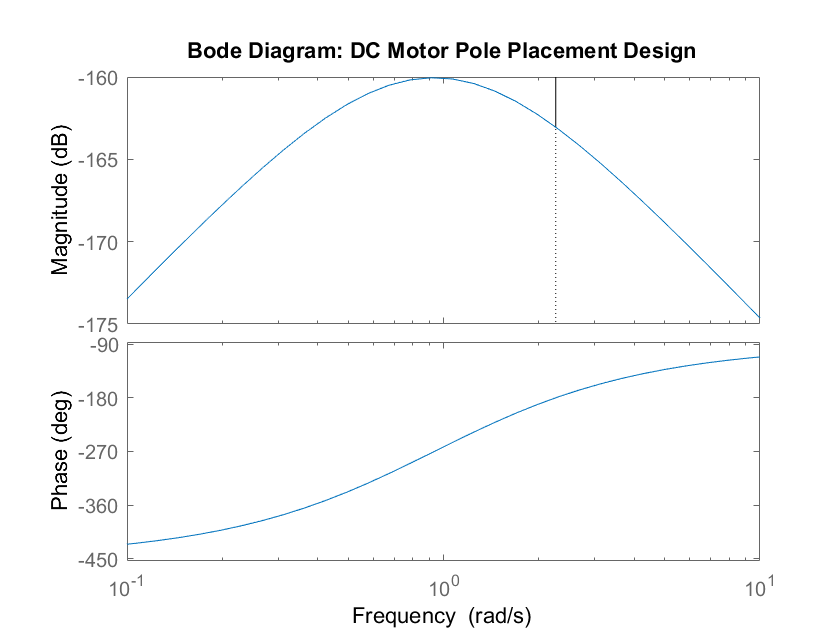


Adc = [-1/.001 -5/.001 0;5 -20 0;0 1 0];
Bdc = [1000;0;0];
Cdc = [0 0 1];
Ddc = [0];
Kdc = [-20; -50; -980];
hdc = .0002;
fundc = @(x) expm(Adc*hdc);
phidc = expm(Adc*hdc);
psidc = integral(fundc,0,hdc,'ArrayValued',1);
gammadc = psidc*Bdc;
[ndc,ddc] = ss2tf(phidc,gammadc,Cdc,Ddc);
figure(13)
margin(ndc,ddc)
title('Bode Diagram: DC Motor Pole Placement Design')

## Maglev Pole Placement Design

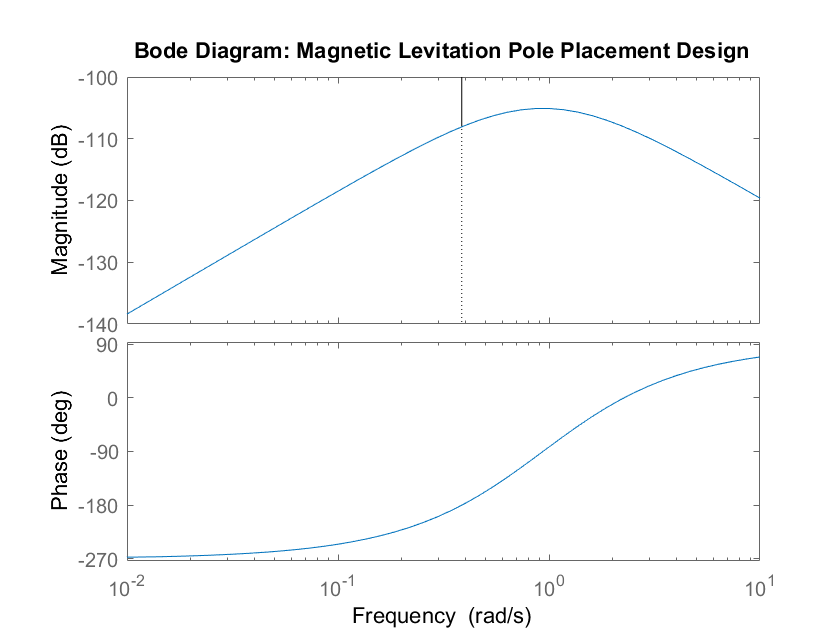


Aml = [0 1 0;1962 0 -28.1;0 0 -100];
Bml = [0;0;100];
Cml = [1 0 0];
Dml = [0];
Kml = [-50; -70; -120];
hml = 0.002;
funml = @(x) expm(Aml*hml);
phiml = expm(Aml*hml);
psiml = integral(funml,0,hml,'ArrayValued',1);
gammaml = psiml*Bml;
[nml,dml] = ss2tf(phiml,gammaml,Cml,Dml);
figure(14)
margin(nml,dml)
title('Bode Diagram: Magnetic Levitation Pole Placement Design')

## Inverted Pendulum Pole Placement Design

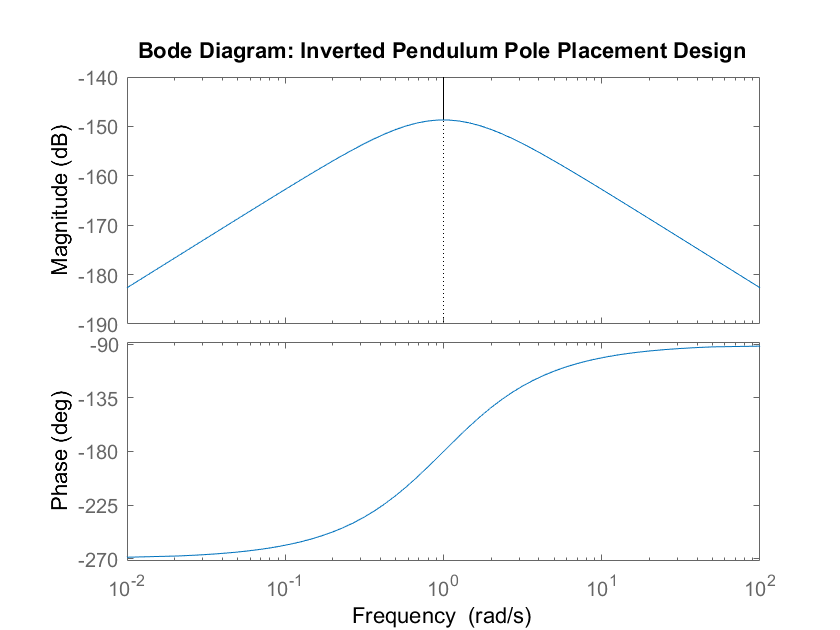


Aip = [0 0 1 0;0 0 0 1;0 11.5 1.84e-3 8.08e-5;0 7.2 8.16e-4 9.18e-5];
Bip = [0;0;0.0184;0.00816];
Cip = [1 0 0 0];
Dip = [0];
Kip = [-1;-1.1;-1.2;-1.3];
hip = 0.002;
funip = @(x) expm(Aip*hip);
phiip = expm(Aip*hip);
psiip = integral(funip,0,hip,'ArrayValued',1);
gammaip = psiip*Bip;
[nip,dip] = ss2tf(phiip,gammaip,Cip,Dip);
figure(15)
margin(nip,dip)
title('Bode Diagram: Inverted Pendulum Pole Placement Design')

## ============================================================

## Cruise Control LQR Design

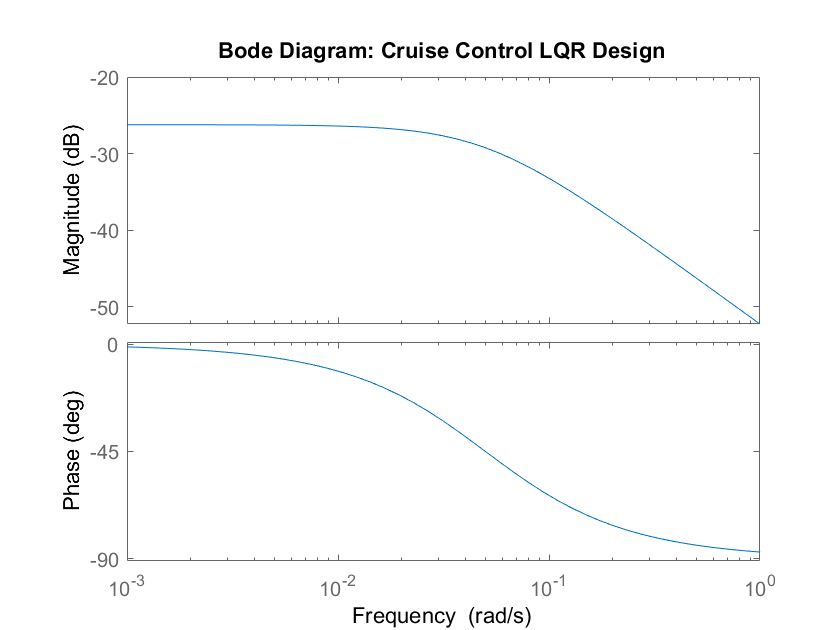


Qcc = [1];
Rcc = 0.001;
Kcc = lqr(Acc,Bcc,Qcc,Rcc);
Gcc = ss(Acc,Bcc,Kcc,0);
figure(16)
margin(Gcc)
title('Bode Diagram: Cruise Control LQR Design')

## DC Motor LQR Design

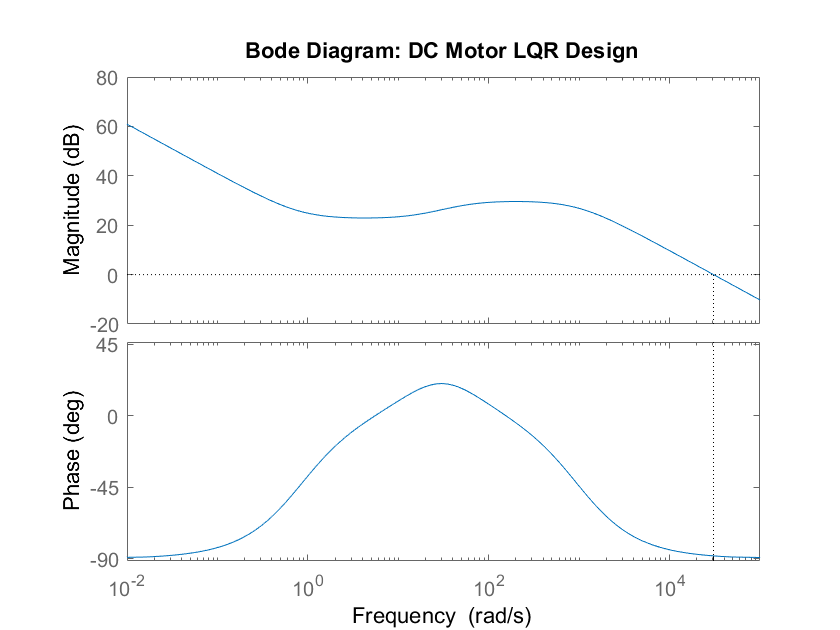


Qdc = [1 0 0;0 1 0;0 0 10];
Rdc = 0.001;
Kdc = lqr(Adc,Bdc,Qdc,Rdc);
Gdc = ss(Adc,Bdc,Kdc,0);
figure(17)
margin(Gdc)
title('Bode Diagram: DC Motor LQR Design')

## Mag Lev LQR Design

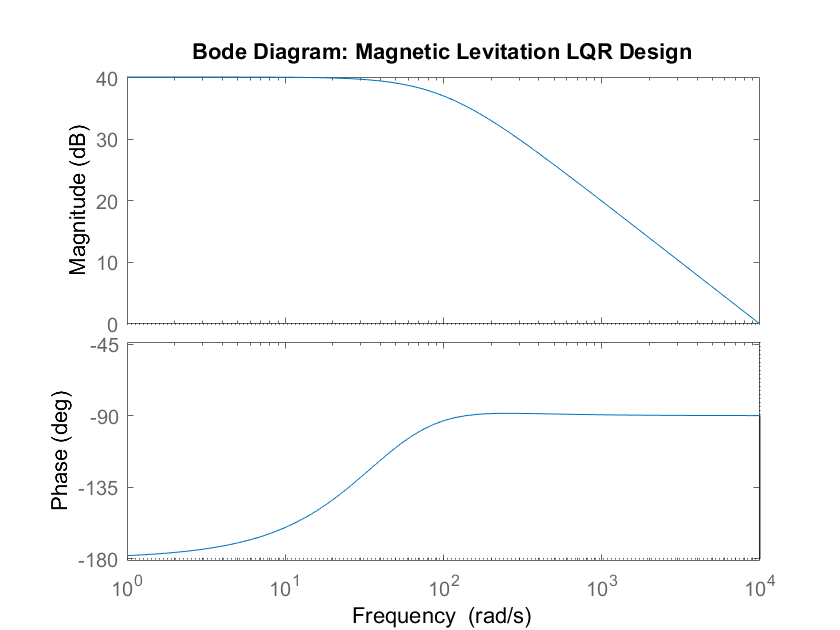


Qml = [1 0 0;0 1 0;0 0 10];
Rml = 0.001;
Kml = lqr(Aml,Bml,Qml,Rml);
Gml = ss(Aml,Bml,Kml,0);
figure(18)
margin(Gml)
title('Bode Diagram: Magnetic Levitation LQR Design')

## Inverted Pendulum LQR Design

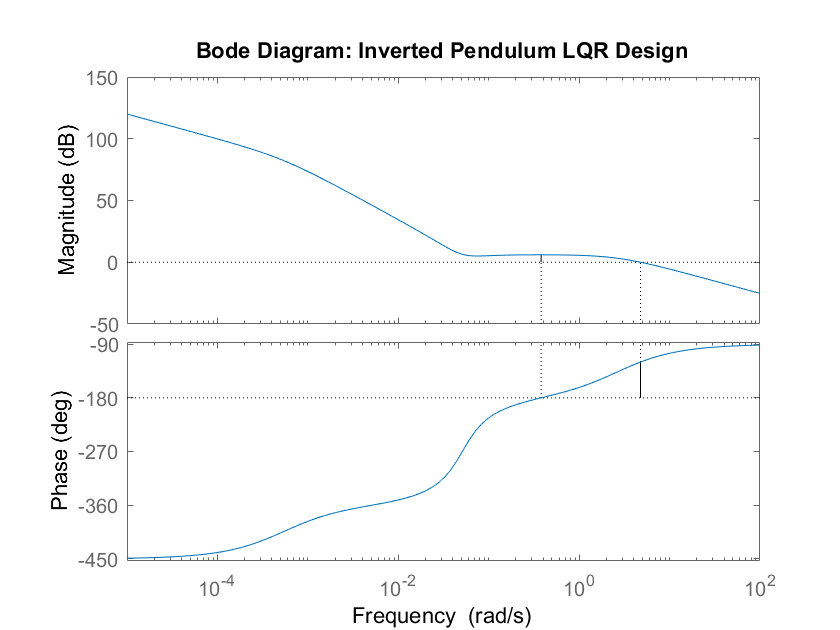


Qip = [1 0 0 0;0 1 0 0;0 0 10 0;0 0 0 100];
Rip = 1;
Kip = lqr(Aip,Bip,Qip,Rip);
Gip = ss(Aip,Bip,Kip,0);
figure(19)
margin(Gip)
title('Bode Diagram: Inverted Pendulum LQR Design')